# Tune Experiment Hyperparameters by Using Bayesian Optimization

Bayesian optimization in [Experiment Manager](https://www.mathworks.com/help/deeplearning/ref/experimentmanager-app.html) can be used to find optimal network hyperparameters and training options for convolutional neural networks. Bayesian optimization provides an alternative strategy to sweeping hyperparameters in an experiment. You specify a range of values for each hyperparameter and select a metric to optimize, and Experiment Manager searches for a combination of hyperparameters that optimizes your selected metric. 

|=============================================================================================================================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | MainBranch1_-| MainBranch2_-| MainBranch1_-| MainBranch2_-| MainBranch1_-| MainBranch2_-| MainBranch1_-| MainBranch2_-|      Dropout | InitialLearn-|
|      | result |             | runtime     | (observed)  | (estim.)    | initial_laye | initial_laye | second_layer | second_layer | third_layer  | third_layer  | fourth_layer | fourth_layer |              | ingRate      |
|=============================================================================================================================================================================================================================|
|    1 | Best   |     0.57963 |      4.9403 |     0.57963 |     0.57963 |            7 |            3 | 

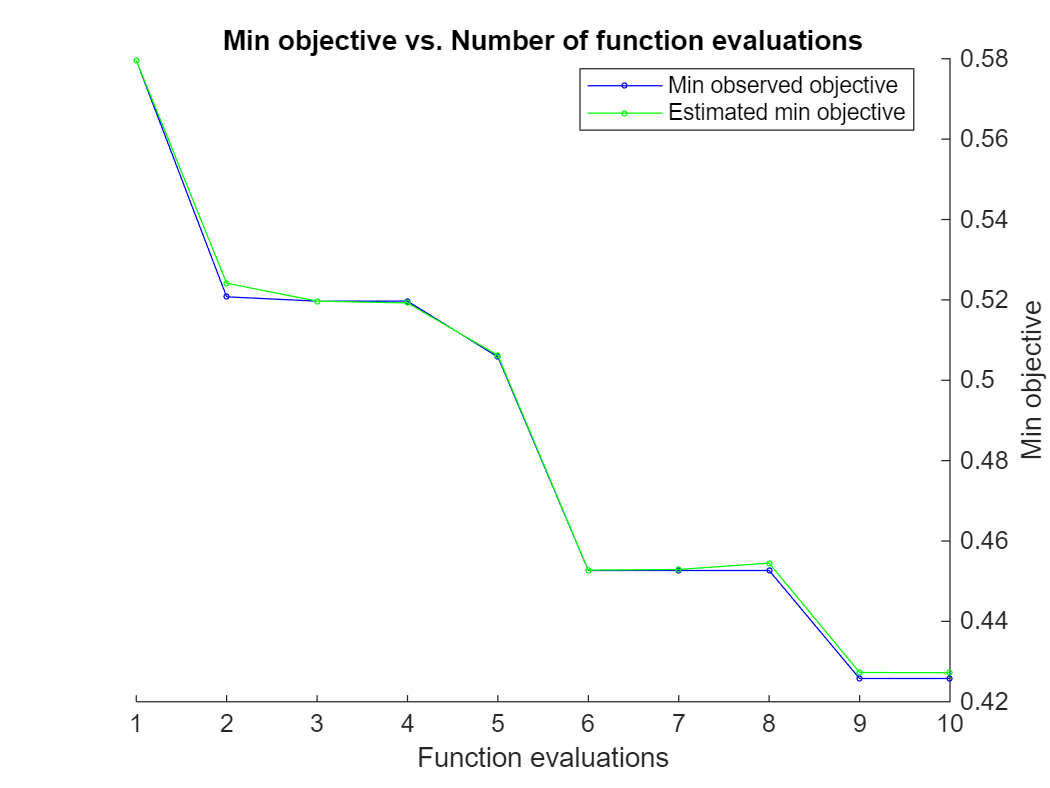

% Switching through several network configurations and number of iterations

% Set up layer structure parameters and training options
params = [
    optimizableVariable('MainBranch1_initial_layer',[1 32],'Type','integer')
    optimizableVariable('MainBranch2_initial_layer',[1 24],'Type','integer')
    optimizableVariable('MainBranch1_second_layer',[1 16],'Type','integer')
    optimizableVariable('MainBranch2_second_layer',[1 12],'Type','integer')
    optimizableVariable('MainBranch1_third_layer',[1 8],'Type','integer')
    optimizableVariable('MainBranch2_third_layer',[1 6],'Type','integer')
    optimizableVariable('MainBranch1_fourth_layer',[1 4],'Type','integer')
    optimizableVariable('MainBranch2_fourth_layer',[1 3],'Type','integer')
    optimizableVariable('Dropout',[0.1 0.9], 'Type','real')
    optimizableVariable('InitialLearningRate',[0.01 0.1], 'Type','real')
    ];
    
obj_function = hyperparameterstuning(Ds_Train, Ds_Validate, Ds_Test);

BayesObject = bayesopt(obj_function,params, ...
    'MaxTime',60*60, ...
    'MaxObjectiveEvaluations', 10, ...
    'IsObjectiveDeterministic',false, ...
    'UseParallel',false);

## Visualize and save the best solution

Tune hyperparameters of a specific model by selecting the hyperparameter values and cross-validating the model using those values. Search for the parameters that give the lowest cross-validation error. Return the best feasible point in the Bayesian model `results` by using the `bestPoint` function. 

zbest = bestPoint(BayesObject); 
trainedNet_bayesopt = BayesObject.UserDataTrace{end}; 
ypred_opt = predict(trainedNet_bayesopt,XTest);

Perform tests using the trained network and report Mean Squared Errors (MSE). 

squaredDifferences = (ypred_opt - TTest).^2;
mse = mean(squaredDifferences) 

mse = single
   0.0124540


## Export to ONNX 

Export to  ONNX models within MATLAB for interoperability with other deep learning frameworks. 

exportONNXNetwork(trainedNet_bayesopt, "bayesOptONNX.onnx"); 


### Upload the ONNX model to ST Development Cloud to benchmark the performance

After completing the initial network design, the next step in the workflow is to assess the performance of that design on a microcontroller or microprocessor. Specifically, engineers need to evaluate the flash and RAM requirements of the network as well as inference speed, among other factors.

web("https://stm32ai-cs.st.com/home");